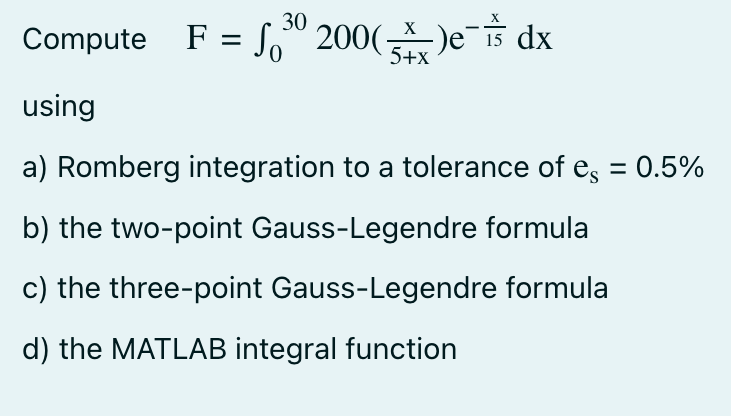

f = @(x) 200 * (x ./ (5 + x)) .* exp(-(x ./ 15));
a = 0;
b = 30;

[I_rom, ea, iter] = romberg(f, a, b, 0.5);
fprintf('I_romberg = %.4f', I_rom)

I_romberg = 1476.7973

% two-point
a1 = (b + a) / 2;
a2 = (b - a) / 2;
f2 = @(xd) (200 * ((a1 + a2 * xd) ./ (5 + (a1 + a2 * xd))) .* exp(-((a1 + a2 * xd) ./ 15))) * a2;

c0 = 1;
c1 = 1;
x0 = -1 / sqrt(3);
x1 = 1 / sqrt(3);
I_gauss2 = c0 * f2(x0) + c1 * f2(x1);
fprintf('I_gauss2 = %.4f', I_gauss2)

I_gauss2 = 1610.5723

% three-point
c0 = 5/9;
c1 = 8/9;
c2 = 5/9;
x0 = -sqrt(3/5);
x1 = 0.0;
x2 = sqrt(3/5);

I_gauss3 = c0 * f2(x0) + c1 * f2(x1) + c2 * f2(x2);
fprintf('I_gauss3 = %.4f', I_gauss3)

I_gauss3 = 1510.3329

I_integral = integral(f, a, b);
fprintf('I_integral = %.4f', I_integral)

I_integral = 1480.5685